# Linear Control Design 2 - Fall 2018 - Exam Part I

## Introduction

The Part I of the Exam in Linear Control Design 2 (E18) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**The scoring of each problem is clearly stated.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E18'

Exam = 'LCD2 E18'

Student_Name = 'Student Name'

Student_Name = 'Student Name'

Student_Number = 'Student Number'

Student_Number = 'Student Number'

## Output feedback control of a mixing tank

A mixing tank is a dynamical system where a liquid with temperature $T_k$ and volume flow $Q_k$ is mixed with another liquid with temperature $T_v$ and volume flow $Q_v$. It is assumed that the mixed liquid is stirred so that its temperature $T_u$ is approximately the same everywhere in the tank. The temperature of the released liquid at the outlet is $T_u$ (the same as in the tank) and the volume flow is $Q_u$. The outlet valve has a constant but adjustable area setting $A_v$.  The two volume flows $Q_k$ and $Q_v$ are determined by individual control valves which receive the input voltages $U_1$ and $U_2$. The level $H$ of the mixed flow in the tank and the temperature $T_u$ are measured with transducers whose outputs are the voltages $Y_1$ and $Y_2$. The following figure shows a schematic of the mixing tank.

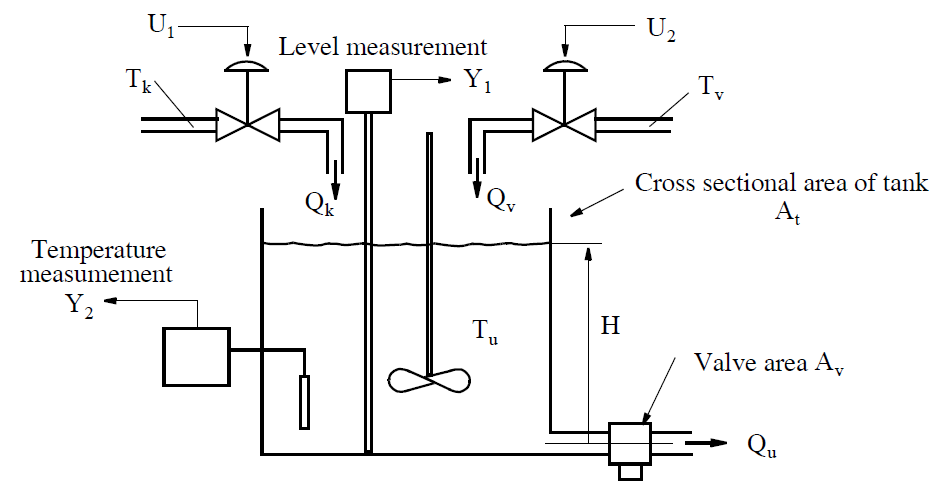

**System Dynamics**

The nonlinear dynamics of the mixing tank is described by the following equations:

- Conservation of mass/volume: $A_t\frac{dH}{dt} = Q_k+Q_v-Q_u$, where $A_t$ is the cross-sectional area of the tank

- Conservation of energy: $A_t\rho c\frac{d}{dt}(T_uH) = \rho c (Q_kT_k + Q_vT_v - Q_uT_u)$, where $\rho$ is the mass density and $c$ is the specific heat capacity of the liquid.

- Flow equation for both control valves: $Q = C_v U$, where $C_v$ is the valve flow coefficient

- Temperature measurement: $Y_1 = k_tT_u$, where $k_t$ is the transducing constant

- Level measurement: $Y_2 = k_hH$, where $k_h$ is the transducing constant

Let the state vector be $\mathbf{x} = [H,T_u]^T$ and the output vector be $\mathbf{y} = [Y_1,Y_2]^T$. Then the nonlinear state space representation of the system is


$$\dot{x}_1 = \frac{1}{A_t}\left(C_v\left(U_1 + U_2\right)-k_v A_v \sqrt{H}\right)$$



$$\dot{x}_2 = \frac{C_v}{A_t H}\left(\left(T_k - T_u\right)U_1 + \left(T_v - T_u\right)U_2\right)$$



$$y_1 = k_tT_u$$



$$y_2 = k_hH$$


The nonlinear model is implemented in the Simulink file MixingTank_NonlinearModel_SimulinkYYYYC, where YYYYC refers to the Simulink version (2017b, 2017a, 2016b, etc.). The numerical values for the model parameters are provided right below.

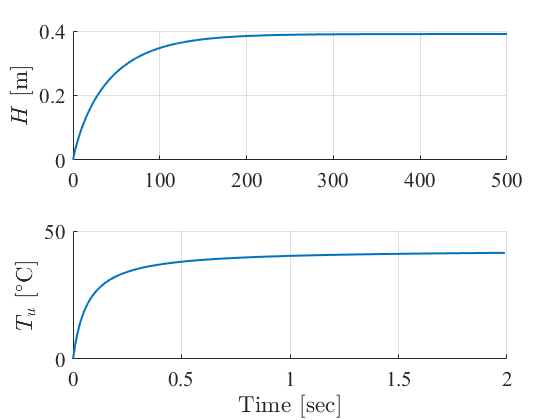

% Simulator parameters (RG)
SIM_TIME = 500; % simulation time (can be changed as needed)
STEP_SIZE = 0.01; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'MixingTank_NonlinearModel_Simulink2017b';

% Model paramters (RG)
% System parameters
At = 0.2; % tank cross-sectional area [m^2]
kv = 0.004; % valve flow coefficient [m^(5/2)/sec]
Av = 1.2; % valve area (dimensionless parameter)
Cv = 0.0005; % valve flow coefficient [m^3/(sec*V)]
kt = 0.1; % transducer constant [0.1 V/degC]
kh = 5; % transducer constant [V/m]
Tk = 25; % temperature [deg]
Tv = 60; % temperature [deg]

% Test the provided nonlinear model (RG)
time = (0:STEP_SIZE:SIM_TIME)';
x0 = [0.001,0]; % initial condition x0 = [H,Tu]'. The initial condition for H is different 
% from zero because in the second differential equation we divide by H and a zero initial 
% condition will give rise to an infinite rate of change.
U10 = 3; % input voltage valve 1 [V]
U20 = 3; % input voltage valve 2 [V]
U = [U10 U20].*ones(length(time),1); % controllable inputs
D = [Tk Tv Av].*ones(length(time),1); % disturbances
sim(SIMULINK_FILENAME,SIM_TIME,[],[time U D])

% Plot temporal behaviour of the state of the nonlinear model (RG)
H = logsout.getElement(1).Values.Data;
Tu = logsout.getElement(2).Values.Data;

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,H,'LineWidth',1.5)
ylabel('$H$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time(1:200),Tu(1:200),'LineWidth',1.5)
ylabel('$T_u$ [$^\circ$C]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

## Operating point and linearization

**Problem 1 [2 points] **Numerically determine the operating point $\mathbf{u}_0$ of the valves $U_1$ and $U_2$ associated with the stationary state $\mathbf{x}_0=[0.8,38]^T$ and while keeping the disturbances constant at their nominal values, i.e. $\mathbf{d}_0=[T_k,Tv,Av]^T = [25,60,1.2]^T$.  Linearize the system around the operatig point $(\mathbf{x}_0,\mathbf{u}_0,\mathbf{d}_0)$.

% Your solution goes here


## Stability analysis

**Problem 2 [2 points]** Assess the internal and external stability of the linear system.

% Your solution goes here


## Control system design for regulation of level and temperature

The main control objective is to regulate the level $H$ and the temperature $T_u$ of the mixed liquid at the desired set-points despite the action of the disturbances $T_k, T_v$ and $A_v$.

Closed-loop system requirements

1) The steady state error for both outputs must be zero in relation to step changes of the set-points and/or the disturbances.

2) For step changes of $\pm20\%$ of the nominal value of $A_v$ the controller regulates the fluid level $H$ with

        a) a maximum overshoot/downshoot in the range 3% - 5%  

        b) a settling time between 50 and 100 seconds

**Problem 3 [6 points]** Under the assumption that the state is fully accessible design a discrete time controller that meets the aforementioned specifications on the nonlinear system using the eigenstructure assignment method. Validate your design through simulation on the linear and nonlinear model.

% Your solution goes here


## Observer design for estimation of the valve area $A_v$

To determine the unknown valve area $A_v$ determining the output flow $Q_u$ and thereby affecting the liquid level $H$, a state estimator in the form of a Kalman filter can be employed.

The two measured outputs are affected by uncorrelated white noise sources $[v_t,v_h]^T$ with zero mean and maximum amplitudes of $\pm 0.05$volts, i.e.


$$y_1 = k_tT_u + v_t \\
y_2 = k_hH + v_h$$


**Problem 4 [4 points]** Under the assumption that the valve area $A_v$ is constant, design a discrete time Kalman filter able to reconstruct the state vector and the unknown valve area. 

% Your solution goes here


**Problem 5 [4 points] **Assess the estimation performance of the Kalman filter when tested on the open loop nonlinear system for step changes of $\pm20\%$ of the nominal value of $A_v$.

% Your solution goes here
